clear all
clc
close all

nntraintool('close');
nnet.guis.closeAllViews();

% Neural networks have weights randomly initialized before training.
% Therefore the results from training are different each time. To avoid
% this behavior, explicitly set the random number generator seed.
rng('default')

% Load the training data into memory
load('digittrain_dataset.mat');

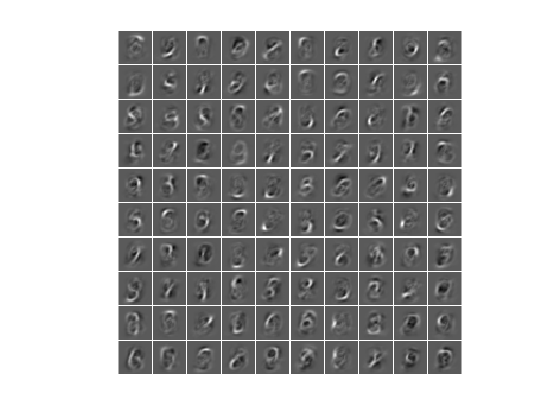

% Layer 1
hiddenSize1 = 100;
autoenc1 = trainAutoencoder(xTrainImages,hiddenSize1, ...
    'MaxEpochs',250, ...
    'L2WeightRegularization',0.004, ...
    'SparsityRegularization',4, ...
    'SparsityProportion',0.15, ...
    'ScaleData', false);

figure;
plotWeights(autoenc1);

feat1 = encode(autoenc1,xTrainImages);

% Layer 2
hiddenSize2 = 50;
autoenc2 = trainAutoencoder(feat1,hiddenSize2, ...
    'MaxEpochs',200, ...
    'L2WeightRegularization',0.002, ...
    'SparsityRegularization',4, ...
    'SparsityProportion',0.1, ...
    'ScaleData', false);

feat2 = encode(autoenc2,feat1);

% Layer 3
softnet = trainSoftmaxLayer(feat2,tTrain,'MaxEpochs',400);

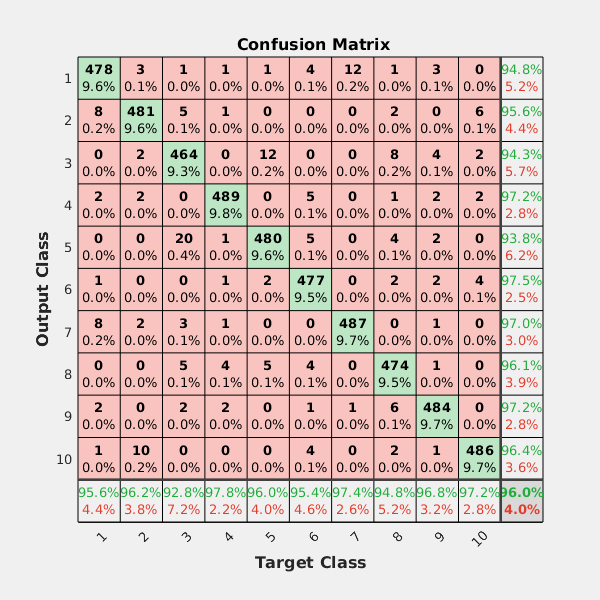

% Deep Net
deepnet = stack(autoenc1,autoenc2,softnet);

% Test deep net
imageWidth = 28;
imageHeight = 28;
inputSize = imageWidth*imageHeight;
load('digittest_dataset.mat');
xTest = zeros(inputSize,numel(xTestImages));
for i = 1:numel(xTestImages)
    xTest(:,i) = xTestImages{i}(:);
end
y = deepnet(xTest);
figure;
plotconfusion(tTest,y);

classAcc=100*(1-confusion(tTest,y))

classAcc = 96

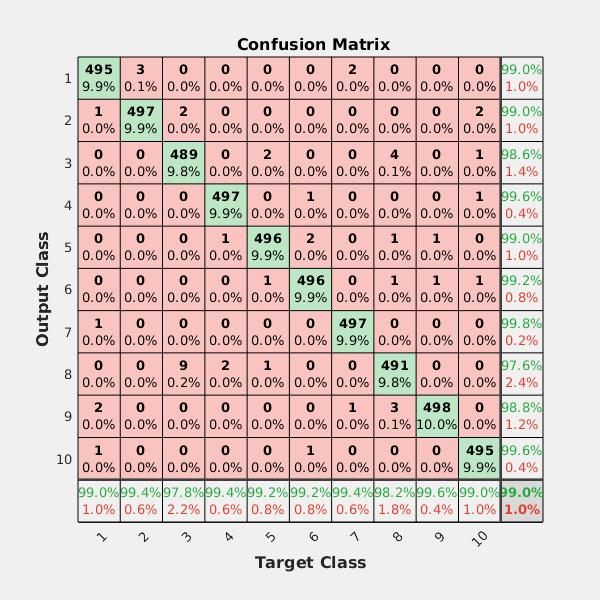

% Test fine-tuned deep net
xTrain = zeros(inputSize,numel(xTrainImages));
for i = 1:numel(xTrainImages)
    xTrain(:,i) = xTrainImages{i}(:);
end
deepnet = train(deepnet,xTrain,tTrain);
y = deepnet(xTest);
figure;
plotconfusion(tTest,y);

classAcc=100*(1-confusion(tTest,y))

classAcc = 99.0200

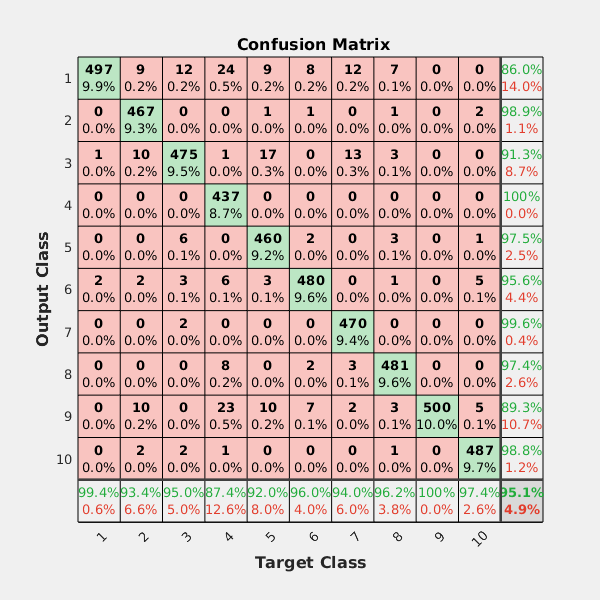

view(deepnet)

%Compare with normal neural network (1 hidden layers)
net = patternnet(100);
net=train(net,xTrain,tTrain);
y=net(xTest);
plotconfusion(tTest,y);

classAcc=100*(1-confusion(tTest,y))

classAcc = 95.0800

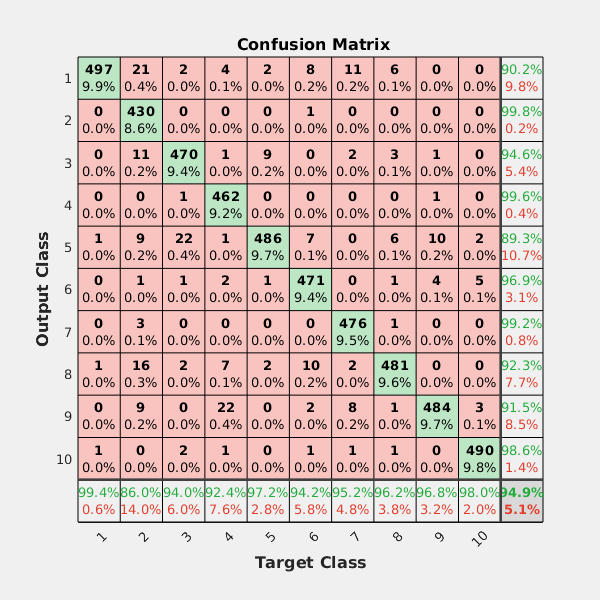

view(net)

%Compare with normal neural network (2 hidden layers)
net = patternnet([100 50]);
net=train(net,xTrain,tTrain);
y=net(xTest);
plotconfusion(tTest,y);

classAcc=100*(1-confusion(tTest,y))

classAcc = 94.9400

view(net)